clc; clear; close all;
a = load("variable_a2.txt")

a =     9.8276
    9.7920
    9.8215
    9.8002
    9.8372
    9.7991
    9.8245
    9.8356
    9.8171
    9.7949


b = load("variable_b2.txt")

b = 	1.0e+04 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0


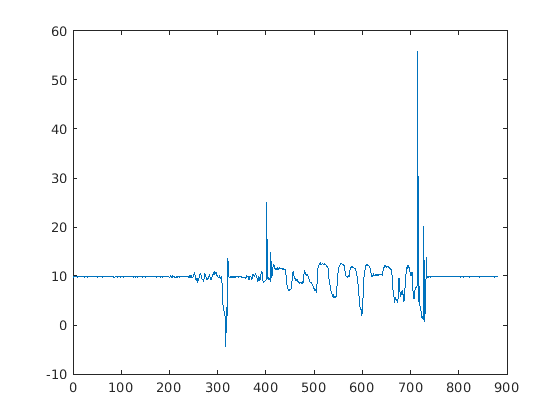

plot(a)

plot(b)

a = sort(a);
b = sort(b);
[len_a, ~] = size(a)

len_a = 883

len_b = 883


for i = 1:len_a
    if a(i) > 13
        a(i) = 0;
    end
end

a = nonzeros(a')

a =    -4.3341
    0.7287
    1.1202
    1.2694
    1.3257
    1.5352
    1.5848
    1.7689
    1.8539
    1.9540


%b = nonzeros(b')

a = normalize(a, "range")

a =          0
    0.2970
    0.3200
    0.3288
    0.3321
    0.3444
    0.3473
    0.3581
    0.3631
    0.3689


b = normalize(b, "range")

b =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



[len_a, ~] = size(a)

len_a = 877

[len_b, ~] = size(b)

len_b = 883

a_30 = a(round(0.5*len_a)-3+194:len_a)

a_30 =     0.8318
    0.8321
    0.8321
    0.8322
    0.8322
    0.8322
    0.8323
    0.8324
    0.8327
    0.8329


b_30 = b(round(0.5*len_b)+194:len_b)

b_30 =     0.6999
    0.6999
    0.6999
    0.6999
    0.6999
    0.6999
    0.6999
    0.6999
    0.6999
    0.6999


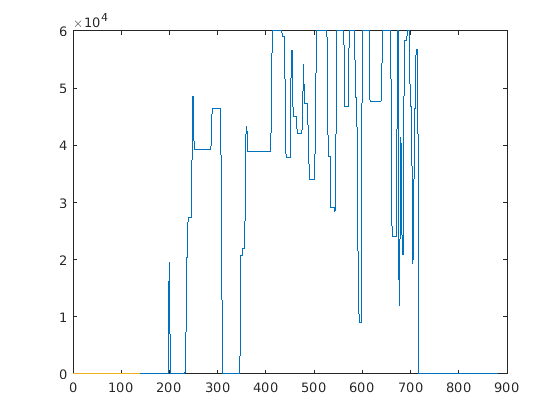

a_30 = a_30(1:139);
b_30 = b_30(1:139);
figure(1)
hold on

plot(a_30)
plot(b_30)
hold off

[et, to] = polyfit(b_30, a_30, 1)

et =     0.2623    0.6444


to = struct with fields:
        R: [2×2 double]
       df: 137
    normr: 0.0684


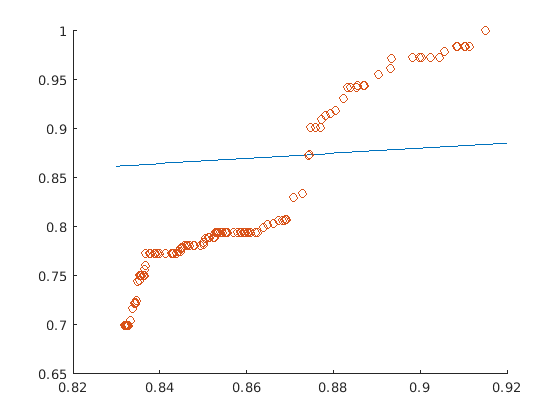

syms x
figure(2)
hold on
fplot(et(1)*x+et(2), "XRange", [0.83 0.92])

scatter(a_30,b_30)
hold off